clc; clear; close all;

1) Read data

trainMat = readmatrix("train_FD001.txt");
testMat  = readmatrix("test_FD001.txt");

% Some MATLAB versions may return trailing NaN columns because of spaces,
% so i will remove them

if size(trainMat,2) >= 28
    trainMat(:,27:28) = [];
end
if size(testMat,2) >= 28

    testMat(:,27:28) = [];
end

2) Assign column names 

columns = { ...
    'unit_number','time_in_cycles','setting_1','setting_2','TRA','T2','T24','T30','T50','P2','P15','P30','Nf', ...
    'Nc','epr','Ps30','phi','NRf','NRc','BPR','farB','htBleed','Nf_dmd','PCNfR_dmd','W31','W32'};

% Convert to tables 
trainTbl = array2table(trainMat, 'VariableNames', columns);
testTbl  = array2table(testMat,  'VariableNames', columns);

3) Describe data 


disp("Summary (train):");

Summary (train):


summary(trainTbl)


trainTbl: 20631×26 table

Variables:

    unit_number: double
    time_in_cycles: double
    setting_1: double
    setting_2: double
    TRA: double
    T2: double
    T24: double
    T30: double
    T50: double
    P2: double
    P15: double
    P30: double
    Nf: double
    Nc: double
    epr: double
    Ps30: double
    phi: double
    NRf: double
    NRc: double
    BPR: double
    farB: double
    htBleed: double
    Nf_dmd: double
    PCNfR_dmd: double
    W31: double
    W32: double

Statistics for applicable variables:

     

vars = trainTbl.Properties.VariableNames;
statsTbl = table('Size',[numel(vars) 8], ...
    'VariableTypes', repmat("double",1,8), ...
    'VariableNames', {'Count','Mean','Std','Min','P25','Median','P75','Max'}, ...
    'RowNames', vars);

for i = 1:numel(vars)
    x = trainTbl.(vars{i});
    x = x(~isnan(x));
    statsTbl.Count(i)  = numel(x);
    statsTbl.Mean(i)   = mean(x);
    statsTbl.Std(i)    = std(x);
    statsTbl.Min(i)    = min(x);
    statsTbl.P25(i)    = prctile(x,25);
    statsTbl.Median(i) = median(x);
    statsTbl.P75(i)    = prctile(x,75);
    statsTbl.Max(i)    = max(x);
end

disp("Stats table (train) like pandas.describe():");

Stats table (train) like pandas.describe():


disp(statsTbl);

                      Count       Mean           Std          Min        P25      Median     P75       Max  
                      _____    ___________    __________    _______    _______    ______    ______    ______

    unit_number       20631         51.507        29.228          1         26        52        77       100
    time_in_cycles    20631         108.81        68.881          1         52       104       156       362
    setting_1         20631    -8.8701e-06     0.0021873    -0.0087    -0.0015         0    0.0015    0.0087
    setting_2         20631     2.3508e-06    0.00029306    -0.0006    -0.0002         0    0.0003    0.0006
    <

4) Plot histograms for each column 

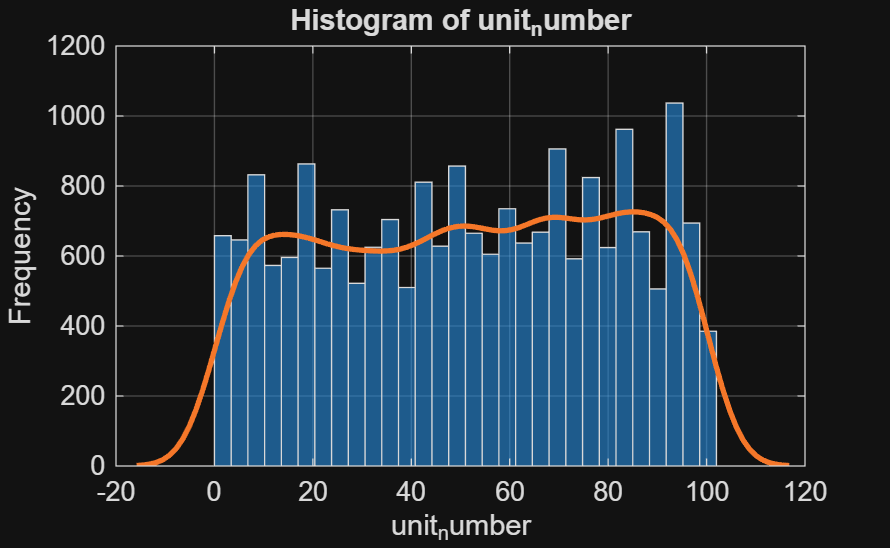

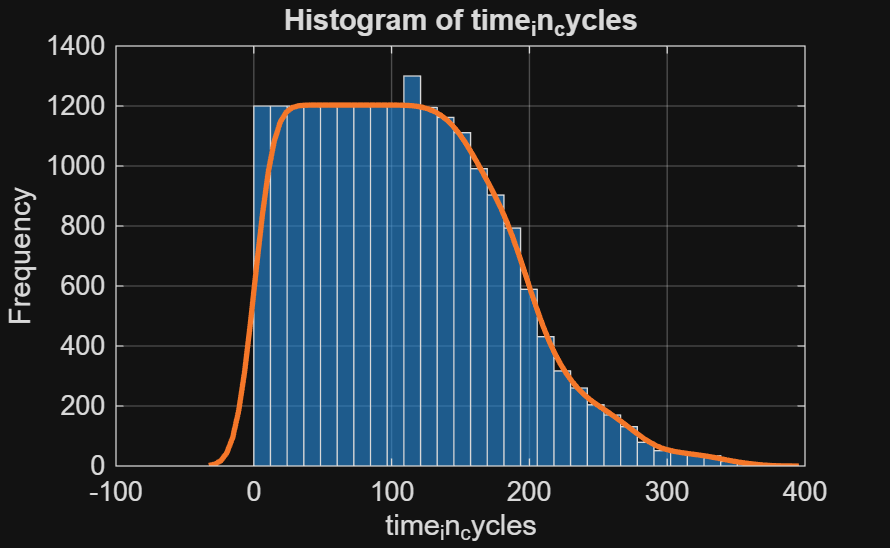

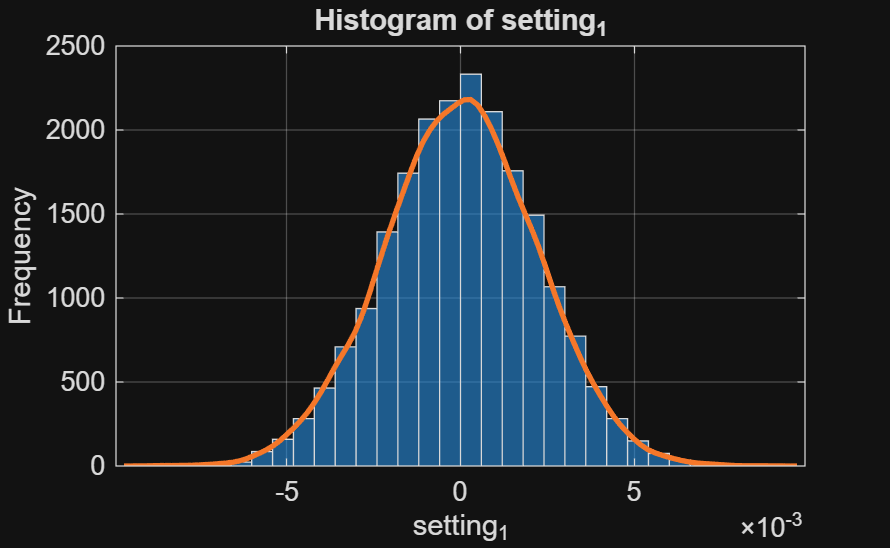

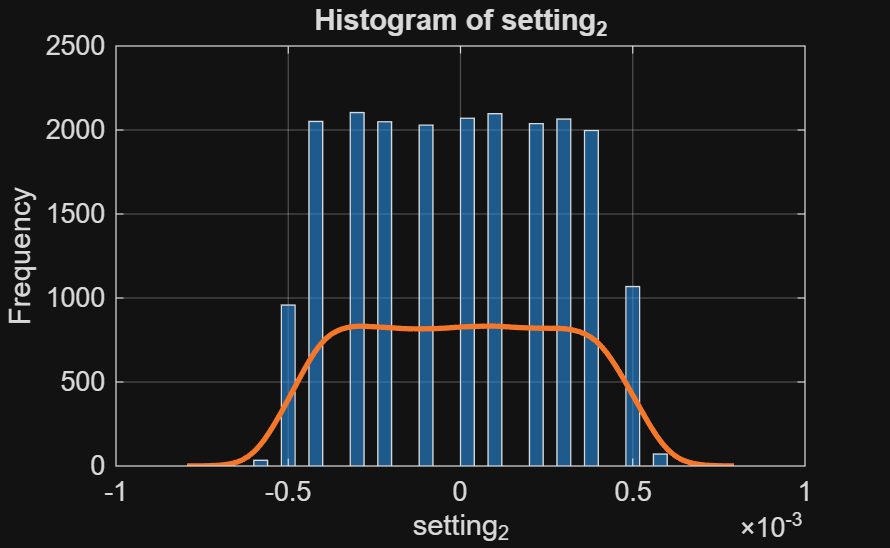

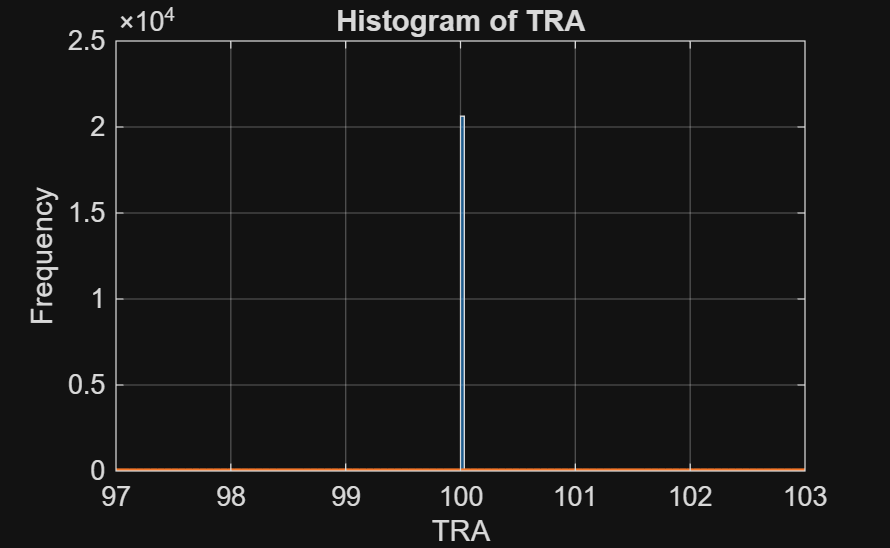

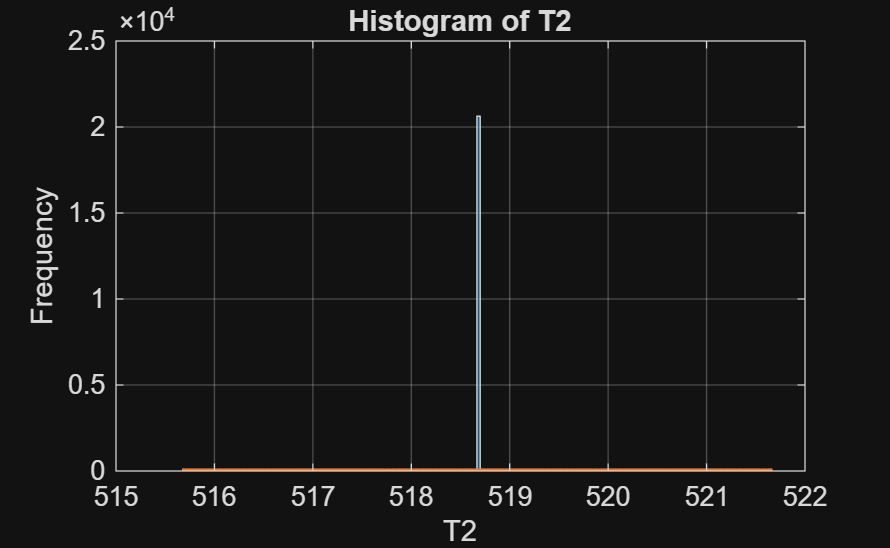

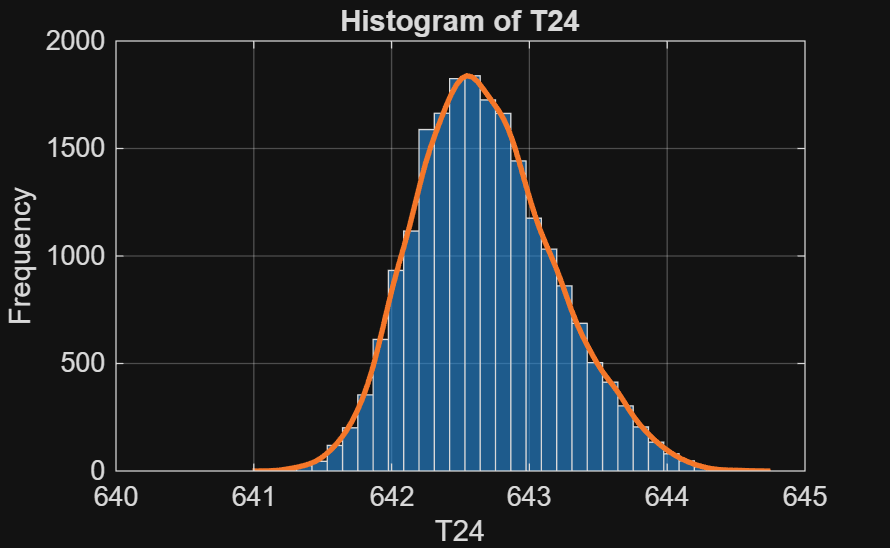

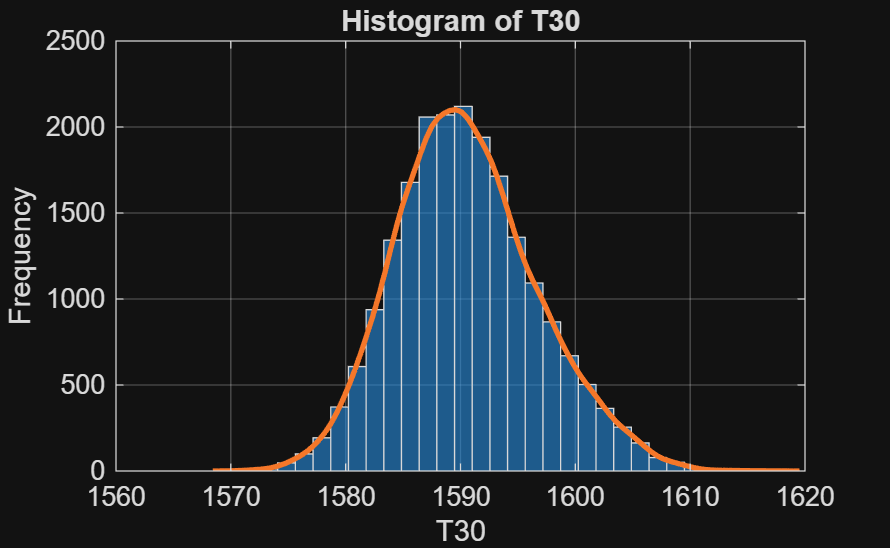


for i = 1:numel(vars)
    x = trainTbl.(vars{i});
    x = x(~isnan(x));

    figure('Position',[200 200 650 400]);
    histogram(x, 30); 
    hold on;

    % KDE 
    if numel(x) > 5
        [f, xi] = ksdensity(x);
        h = gca;
        binWidth = (max(x)-min(x))/30;
        plot(xi, f * numel(x) * binWidth, 'LineWidth', 2);
    end

    title("Histogram of " + vars{i});
    xlabel(vars{i});
    ylabel("Frequency");
    grid on;
    hold off;
end

%% 5) Drop selected columns
dropVars = {'Nf_dmd','PCNfR_dmd','P2','T2','TRA','farB','epr'};
trainTbl(:, dropVars) = [];
testTbl(:,  dropVars) = [];

disp("Remaining columns after drop:");

Remaining columns after drop:


disp(trainTbl.Properties.VariableNames);

    {'unit_number'}    {'time_in_cycles'}    {'setting_1'}    {'setting_2'}    {'T24'}    {'T30'}    {'T50'}    {'P15'}    {'P30'}    {'Nf'}    {'Nc'}    {'Ps30'}    {'phi'}    {'NRf'}    {'NRc'}    {'BPR'}    {'htBleed'}    {'W31'}    {'W32'}

